**EE 699 Next Generation Wireless Networks**

**Rishabh Pomaje - 210020036**

** Assignment 01**

clear ;

% Simulation constants
n_runs = 1 ;

% Parameter Constants
N_fft = 128 ;          % Size of the FFT
del_F = 15 * 10 ^ 3 ;  % Sub carrier spacing
Fs = N_fft * del_F ;   % Sampling Rate
num_rf = 1 ;           % Number of Radio Frames
t_sample = 1 / del_F;  % Duration of one FFT sample

num_sf = num_rf * 10 ;
num_slots = num_sf * 2 ;

% Force Number of Subframes :
num_sf = 1 ;

% Time axes calculations :
slot_duration = 0.5 * 10 ^ -3 ;
subf_duration = 2 * slot_duration ;
rf_duration = 10 * subf_duration ;
total_duration = num_sf * subf_duration ;

t_axes = 0: 1/Fs: total_duration - (1/Fs) ;

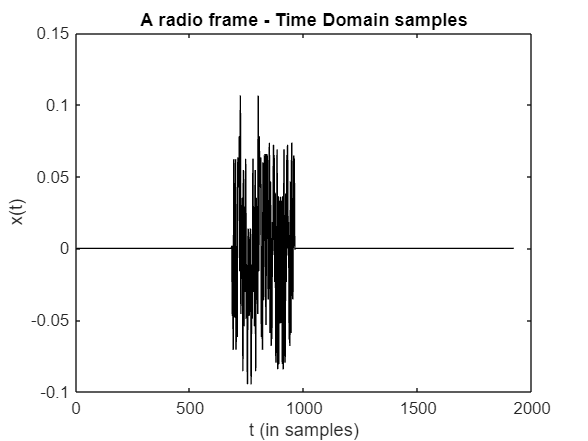

% Demo of the correlation of generated signals in time domain
[x_t, ~, truePSS, ~] = LTEsignalGen(num_sf) ;
plot(real(x_t), Color=[0, 0, 0]) ;
xlabel('t (in samples)') ;
ylabel('x(t)')
title('A radio frame - Time Domain samples') ;

% Creation of reference signals in frequency domain :
[time_refPSS, time_refSSS] = LTErefSignalGen("time") ;
[freq_refPSS, freq_refSSS] = LTErefSignalGen("frequency") ;
truePSS

truePSS = 1

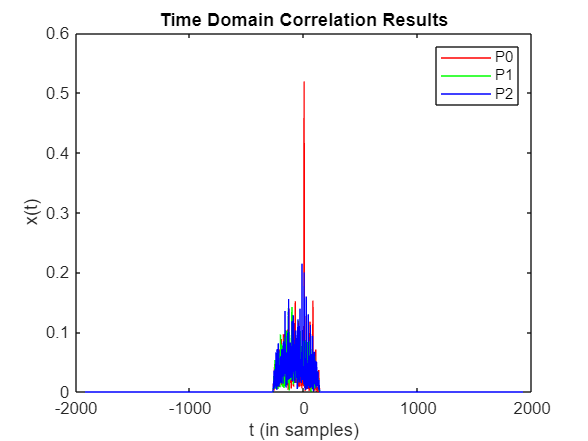

cla ;
hold on ;
[c, lags] = xcorr(x_t, time_refPSS(:, 1)) ;
plot(lags, abs(c), Color=[1, 0, 0]) ;
[c, lags] = xcorr(x_t, time_refPSS(:, 2)) ;
plot(lags, abs(c), Color=[0, 1, 0]) ;
[c, lags] = xcorr(x_t, time_refPSS(:, 3)) ;
plot(lags, abs(c), color=[0, 0, 1]) ;
legend('P0', 'P1', 'P2') ;
title('Time Domain Correlation Results') ;
hold off;

- PSS and SSS Detection - For AWGN channel 

mse_T0_awgn = [] ;
mse_F0_awgn = [] ;
Pe_PSS_id_awgn = [] ;
Pe_SSS_id_awgn = [] ;

% Simulation routine
SNR_dB = -2:15 ;

% Generate a signal
[x_t, truPSSid, truSSSid] = LTEsignalGen(1) ;
% Add a time offset :: In number of samples
t_off_ideal = randi(9) ;
x_t = [zeros(t_off_ideal, 1); x_t] ;

% Channel Reponse : AWGN Channel
mu = 0 ;
sig2 = 0 ;
noise_samples = normrnd(mu, sig2, size(x_t)) + 1j * normrnd(mu, sig2, size(x_t)) ;

% Received signal y = x + n :
y_t = x_t + noise_samples;

% Add a frequency offset
f_off_ideal = randi([-200, 200]) ;
for n=1:length(y_t)
    y_t(n) = exp(1j * 2 * pi * f_off_ideal * n * t_sample) * y_t(n) ;
end

% Detection of PSS ID using time domain correlation and finding the time offset in number of samples
estPSSid = 0 ;
[c, lags] = xcorr(y_t, time_refPSS(:, 1)) ;
[currPeak, maxInd] = max(abs(c)) ;
currTimeoff = lags(maxInd) ;
for idx=2:3
    [c, lags] = xcorr(y_t, time_refPSS(:, idx)) ;
    [Peak, maxInd] = max(abs(c)) ;
    Timeoff = lags(maxInd) 
    if Peak > currPeak
        estPSSid = idx - 1;
        currPeak = Peak ;
        currTimeoff = Timeoff ;
    end
end

Timeoff = -123

Timeoff = 60

% We need a correction factor as the lag gives me the index the sample from
% the start:
% correction_factor = 137*5 + 138 + 9 ; % 5 Normal CP Symbols + 1 long CP symbol + Samples of CP of PSS
enb.NDLRB = 6;                      % Number of resource blocks
enb.CellRefP = 1;                   % One transmit antenna port
enb.NCellID = truPSSid;    % Cell ID
enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
enb.DuplexMode = 'FDD';             % FDD

lteDLFrameOffset( enb , y_t)

ans = 5


t_off_est = currTimeoff %- correction_factor 

t_off_est = 60

t_off_ideal

t_off_ideal = 1

% Time offset correction :
y_t_offCorrect = y_t(t_off_est+1:length(y_t), 1) ;

% Extracting the received PSS (and dropping the cyclic prefix):
rx_PSS = y_t_offCorrect(824+9:960, 1) ;
% Conversion to frequency domain :
Y_PSS = fft(rx_PSS) ;
% Extract active sub-carriers :
Y_PSS = Y_PSS(34:95, 1) ;

[c, lags] = xcorr(Y_PSS, freq_refPSS(:, 1)) ;
[currPeak, maxInd] = max(abs(c)) ;
temp = maxInd ;
currFreqoff = lags(maxInd) ; 
for idx=2:3
    [c, lags] = xcorr(Y_PSS, freq_refPSS(:, idx)) ;
    [Peak, maxInd] = max(abs(c)) ;
    Freqoff = lags(maxInd) ;
    if Peak > currPeak
        estPSSid = idx - 1 ;
        currPeak = Peak ;
        currFreqoff = Freqoff ;
        temp = maxInd ;
    end
end
temp

temp = 61

f_off_est = currFreqoff 

f_off_est = -1

f_off_ideal

f_off_ideal = 115

PSS and SSS detection - For Rayleigh Fading + AWGN channel

Additions compared to the previous part : Channel Estimation 

**Function definitions :**

function [x_t, X_f, PSS_id, SSS_id] = LTEsignalGen(num_sf)
    % Function that generates time domain samples of LTE signal consisting
    % of PSS and SSS synchronization signals.
    x_t = [] ;
    PSS_id = randi([0, 2]) ;
    SSS_id = randi([0, 15]) ;
    % Cell Settings :
    enb.NDLRB = 6;                      % Number of resource blocks
    enb.CellRefP = 1;                   % One transmit antenna port
    enb.NCellID = 3*SSS_id + PSS_id;    % Cell ID
    enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
    enb.DuplexMode = 'FDD';             % FDD
    % Generation in frequency domain :
    txGrid = [] ;
    for i=0:num_sf - 1
        enb.NSubframe = mod(i, 10); % Subframe Index
        subframe = lteDLResourceGrid(enb);
    
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb) ;
        sss_symbols = lteSSS(enb) ;
        antenna = 0 ;
        pssIndices = ltePSSIndices(enb, antenna) ;
        sssIndinces = lteSSSIndices(enb, antenna) ;
    
        % Map synchronizing signals to the grid
        subframe(pssIndices) = pss_symbols ;
        subframe(sssIndinces) = sss_symbols ;
    
        % Collect all the subframes 
        txGrid = [txGrid subframe] ;
    end
    % Frequency Domain signal
    X_f = txGrid ;
    % Modulation : Conversion to time domain
    [x_t,~] = lteOFDMModulate(enb,txGrid) ;
    end
    
    % My implementation of the OFDM Modulator
    function [x_t, PSS_id, SSS_id] = myOFDMModulator(num_sf)
    x_t = [] ;
    PSS_id = randi([0, 2]) ;
    SSS_id = randi([0, 15]) ;
    % Cell Settings :
    enb.NDLRB = 6;                      % Number of resource blocks
    enb.CellRefP = 1;                   % One transmit antenna port
    enb.NCellID = 3*SSS_id + PSS_id;    % Cell ID
    enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
    enb.DuplexMode = 'FDD';             % FDD
    % Generation in frequency domain :
    for i=0:num_sf - 1
        sf_grid = [] ;
        enb.NSubframe = mod(i, 10); % Subframe Index
    
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb) ;
        sss_symbols = lteSSS(enb) ;
    
        % Zero Padding for 128 pt FFT
        pss_symbols = [zeros(33, 1); pss_symbols; zeros(33, 1)] ;
        sss_symbols = [zeros(33, 1); sss_symbols; zeros(33, 1)] ;
    
        % Taking the FFT
        pss_samples = ifft(pss_symbols) ;
        sss_samples = ifft(sss_symbols) ;
    
        % Adding the CP
        pss_samples = [pss_samples(120:128, 1); pss_samples] ;
        sss_samples = [sss_samples(120:128, 1); sss_samples] ;

        % Forming the subframe in time domain 
        sf_grid = [zeros(686, 1); sss_samples; pss_samples; zeros(960, 1)] ;
        x_t = [x_t sf_grid] ;
    end
end

function [refPSS, refSSS] = LTErefSignalGen(domain)
% Function to generate the reference time domain or frequency domain
% using lteOFDMModulate
% signals of the PSS and SSS for LTE.
refPSS = [] ;
refSSS = [] ;
if (domain == "time")
    % Return the time domain samples
    % PSS sequences : 0 ~ 2
    for PSS_id=0:2
        enb.NDLRB = 6 ;                 % Number of resource blocks
        enb.CellRefP = 1 ;              % One transmit antenna port
        enb.NCellID = PSS_id ;          % Cell ID
        enb.CyclicPrefix = 'Normal' ;   % Normal cyclic prefix
        enb.DuplexMode = 'FDD' ;        % FDD
        enb.NSubframe = 0 ; % Subframe Index

        % Generate synchronizing signals
        pss_symbols = ltePSS(enb) ;
        pssIndices = ltePSSIndices(enb) ;

        PSSsubframe = lteDLResourceGrid(enb);
        PSSsubframe(pssIndices) = pss_symbols;

        % Modulation : Conversion to time domain
        [t_pss,~] = lteOFDMModulate(enb,PSSsubframe) ;
        refPSS = [refPSS t_pss] ;
    end
    % SSS sequences : 0 ~ 15
    for SSS_id=0:3:45
        enb.NDLRB = 6;                 % Number of resource blocks
        enb.CellRefP = 1;              % One transmit antenna port
        enb.NCellID = SSS_id;  % Cell ID
        enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
        enb.DuplexMode = 'FDD';        % FDD
        enb.NSubframe = 0; % Subframe Index

        % Generate synchronizing signals
        sss_symbols = lteSSS(enb);
        sssIndices = lteSSSIndices(enb);

        SSSsubframe = lteDLResourceGrid(enb);
        SSSsubframe(sssIndices) = sss_symbols;

        % Modulation : Conversion to time domain
        [t_sss,~] = lteOFDMModulate(enb,SSSsubframe) ;
        refSSS = [refSSS t_sss] ;
    end
    % Return the frequency domain samples :
else
    % PSS sequences : 0 ~ 2
    for PSS_id=0:2
        enb.NDLRB = 6;                 % Number of resource blocks
        enb.CellRefP = 1;              % One transmit antenna port
        enb.NCellID = PSS_id;  % Cell ID
        enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
        enb.DuplexMode = 'FDD';        % FDD
        enb.NSubframe = 0; % Subframe Index

        % Generate synchronizing signals
        pss_symbols = ltePSS(enb);
        refPSS = [refPSS pss_symbols] ;
    end
    % SSS sequences : 0 ~ 15
    for SSS_id=0:3:45
        enb.NDLRB = 6;                 % Number of resource blocks
        enb.CellRefP = 1;              % One transmit antenna port
        enb.NCellID = SSS_id;  % Cell ID
        enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
        enb.DuplexMode = 'FDD';        % FDD
        enb.NSubframe = 0; % Subframe Index

        % Generate synchronizing signals
        sss_symbols = lteSSS(enb);
        refSSS = [refSSS sss_symbols] ;
    end
end
end

% My implementation of the reference signal generators (only modulation part is mine.)
function [refPSS, refSSS] = myrefSignalGen(domain)
    % Function to generate the reference time domain or frequency domain
    % signals of the PSS and SSS for LTE.
    refPSS = [] ;
    refSSS = [] ;
    if (domain == "time")
        % Return the time domain samples
        % PSS sequences : 0 ~ 2
        for PSS_id=0:2
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = PSS_id;  % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
    
            % Generate synchronizing signals
            pss_symbols = ltePSS(enb);
            pss_symbols = [zeros(33, 1); pss_symbols; zeros(33, 1)] ;
            t_pss = ifft(pss_symbols) ;
    
            % Modulation : Conversion to time domain
            refPSS = [refPSS t_pss] ;
        end
        % SSS sequences : 0 ~ 15
        for SSS_id=0:15
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = 3 * SSS_id;      % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
    
            % Generate synchronizing signals
            sss_symbols = lteSSS(enb);
            sss_symbols = [zeros(33, 1); pss_symbols; zeros(33, 1)] ;
    
            % Modulation : Conversion to time domain
            t_sss = ifft(sss_symbols) ;
            refSSS = [refSSS t_sss] ;
        end
    else
        % Return the frequency domain samples :
        % PSS sequences : 0 ~ 2
        for PSS_id=0:2
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = PSS_id;          % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
    
            % Generate synchronizing signals
            pss_symbols = ltePSS(enb);
            refPSS = [refPSS pss_symbols] ;
        end
        % SSS sequences : 0 ~ 15
        for SSS_id=0:15
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = 3*SSS_id;        % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
    
            % Generate synchronizing signals
            sss_symbols = lteSSS(enb);
            refSSS = [refSSS sss_symbols] ;
        end
    end
end

% function [offset, pssID, sssID] = myLTEreceiver(domain, rxSignal, refSignal, csi, isCoherentDet)
%     % Function that detects and estimates the time and frequency offsets of
%     % the impaired LTE signal.
%     % Domain
%         % Coherent Detection
%             % Channel
%
% end